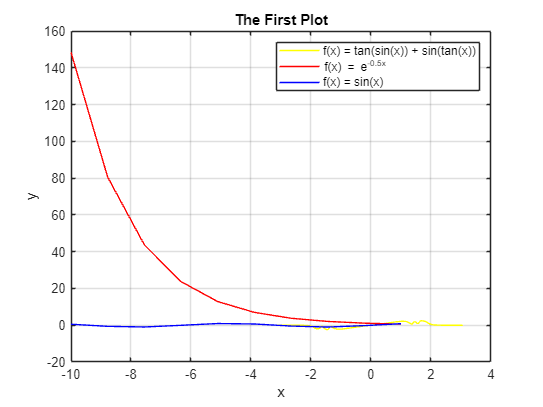

%Task 1
f_x = @(x) tan(sin(x)) + sin(tan(x));

x_values = -pi:0.1:pi;

y_values = f_x(x_values);

figure;
plot(x_values, y_values,'Color', 'yellow');
title('The First Plot');
xlabel('x');
ylabel('f(x)');
grid on;

hold on;

f1_x = @(x) exp(-0.5*x);
f2_x = @(x) sin(x);

x_values = linspace(-10, 1, 10);
y1_values = f1_x(x_values);
y2_values = f2_x(x_values);

semilogy(x_values, y1_values, 'Color', 'red');
plot(x_values, y2_values,'Color', 'blue');
xlabel('x');
ylabel('y');
legend('f(x) = tan(sin(x)) + sin(tan(x))', 'f(x) = e^{-0.5x}', 'f(x) = sin(x)');

hold off;

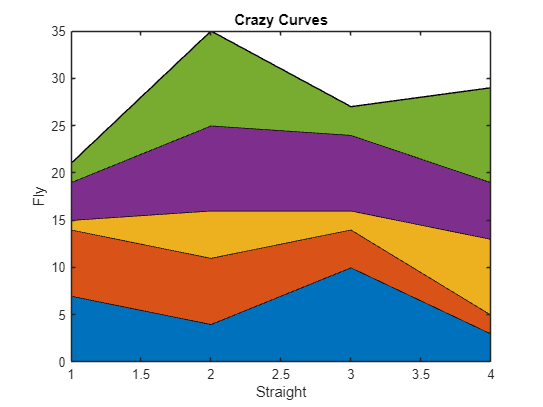


%Task 2

Matrix = randi([1, 10], 4, 5);
area(Matrix);
title('Crazy Curves')
xlabel('Straight');
ylabel('Fly');

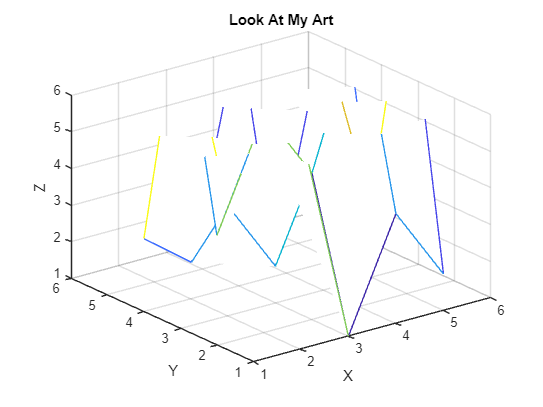


Z = Matrix;
[X, Y] = meshgrid(1:size(Z, 2), 1:size(Z, 1));
mesh(X, Y, Z);

xlim([1 6]);
ylim([1 6]);
zlim([1 6]);

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Look At My Art');

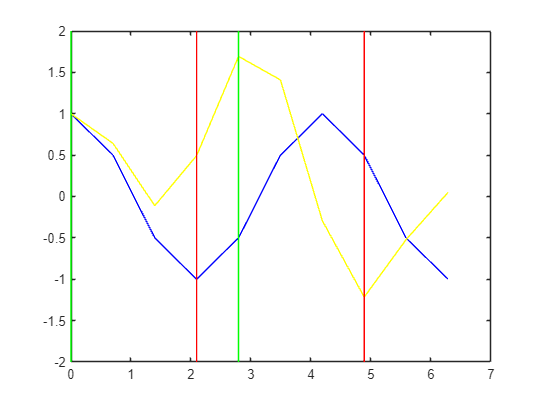


%Task 3

x = linspace(0, 2*pi, 10);

Y1 = cos(1.5 * x);
Y2 = sin(0.7 * x) + cos(2 * x);

plot(x, Y1, 'Blue');
hold on;
plot(x, Y2, 'Yellow');

[minY1, minIdxY1] = min(Y1);
[maxY1, maxIdxY1] = max(Y1);
plot([x(minIdxY1), x(minIdxY1)], [-2, 2], 'Red');
plot([x(maxIdxY1), x(maxIdxY1)], [-2, 2], 'Green');

[minY2, minIdxY2] = min(Y2);
[maxY2, maxIdxY2] = max(Y2);
plot([x(minIdxY2), x(minIdxY2)], [-2, 2], 'Red');
plot([x(maxIdxY2), x(maxIdxY2)], [-2, 2], 'Green');

ylim([-2 2]);